# Flexible joint

## Initialization of parameters

clear all
close all
clc

## Dynamic equations

### DC Motor


$$\left\lbrace \begin{array}{ll}
T=k_t \;i_a  & \\
v_a -k_e \dot{\theta} =R\;i_a +L\;si_a  & 
\end{array}\right.$$

$$\Rightarrow$$
 
$$T=\frac{k_t \left(v_a -k_e \dot{\theta \;} \right)}{R+\textrm{sL}}$$


### Base model

### Mechanical equations


$$J_b \ddot{\;\theta_1 } +B_b \dot{\;\theta_1 \;} =T-T_{\textrm{load}}$$



$$\begin{array}{l}
\theta_1 =\frac{n_r k_t }{s\left\lbrack J_b Ls^2 +\left({\textrm{RJ}}_b +B_b L\right)s+\left({\textrm{RB}}_b +k_t k_e \right)\right\rbrack }v_a -\frac{T_{\textrm{load}} \left(R+\textrm{sL}\right)}{s\left\lbrack J_b Ls^2 +\left({\textrm{RJ}}_b +B_b L\right)s+\left({\textrm{RB}}_b +k_t k_e \right)\right\rbrack }\\
\theta_1 \approx \frac{\mu }{s\left(1+s\tau_1 \right)\left(1+s\tau_2 \right)}v_a +n
\end{array}$$


where:


$$\begin{cases}
\tau_1\tau_2=\frac{J_bL}{RB_b+k_tk_e} \\
\tau_1+\tau_2=\frac{RJ_b+B_bL}{RB_b+k_tk_e} \\
\mu=\frac{n_rk_t}{RB_b+k_tk_e}
\end{cases}$$


### Tip model (whole model, too complex!)

### Mechanical equations


$$J\ddot{\;\theta_2 } +B\dot{\;\theta_2 \;} +k_{\textrm{el}} \left(\theta_2 -\theta_1 \right)=T-T_{\textrm{load}}$$



$$\begin{array}{l}
\theta_2 =\frac{\left(k_{\textrm{el}} L-k_e k_t \right)s+k_{\textrm{el}} R}{J_{\textrm{arm}} Ls^3 +\left({\textrm{RJ}}_{\textrm{arm}} +B_{\textrm{arm}} L\right)s^2 +\left({\textrm{RB}}_{\textrm{arm}} +{\textrm{Lk}}_{\textrm{el}} \right)s+{\textrm{Rk}}_{\textrm{el}} }\theta_1 +\frac{n_r k_t }{J_{\textrm{arm}} Ls^3 +\left({\textrm{RJ}}_{\textrm{arm}} +B_{\textrm{arm}} L\right)s^2 +\left({\textrm{RB}}_{\textrm{arm}} +{\textrm{Lk}}_{\textrm{el}} \right)s+{\textrm{Rk}}_{\textrm{el}} }v_a -\frac{T_{\textrm{load}} }{J_{\textrm{arm}} Ls^3 +\left({\textrm{RJ}}_{\textrm{arm}} +B_{\textrm{arm}} L\right)s^2 +\left({\textrm{RB}}_{\textrm{arm}} +{\textrm{Lk}}_{\textrm{el}} \right)s+{\textrm{Rk}}_{\textrm{el}} }\\
\theta_2 \approx \frac{\mu_1 }{\left(1+s\tau_1 \right)\left(1+s\tau_2 \right)\left(1+s\tau_3 \right)}\theta_1 +\frac{\mu_2 }{\left(1+s\tau_1 \right)\left(1+s\tau_2 \right)\left(1+s\tau_3 \right)}v_a +n
\end{array}$$


### Tip model (from angle)


$$\begin{array}{l}
\theta_2 =\frac{k_{\textrm{el}} }{s^2 J_{\textrm{arm}} +\textrm{Bs}+k_{\textrm{el}} }\theta_1 +\frac{T-T_{\textrm{load}} }{s^2 J_{\textrm{arm}} +\textrm{Bs}+k_{\textrm{el}} }\\
\theta_2 \approx \frac{\mu }{s^2 +2\zeta \omega s+\omega^2 }\theta_1 +n
\end{array}$$


where:


$$\begin{cases}
\mu = \frac{k_{el}}{J_{arm}} \\
\omega = \sqrt{\frac{k_{el}}{J_{arm}}} \\
\zeta = \frac{B_{arm}}{2\sqrt{J_{arm}k_{el}}}
\end{cases}$$


## Data acquisition

Datastruct = load('./Datas_acquisition/Base_impulse_response.mat');
Data = Datastruct.data_03_Mar_2023_10_48_02;

### Data organization

Ts = 0.002;                    %[s], sampling time
U = [Data(3,:)]';              %[N_data x N_inputs], input data matrix

Y_base = [Data(2,:)]';         %[N_data x N_outputs], output data matrix for base
%Y_tip = [ ];         %[N_data x N_outputs], output data matrix for tip

Data_base = iddata(Y_base,U,Ts);
%Data_tip = iddata(Y_tip,U,Ts);

## Model identification

### First approach

Base_model_1 = tfest(Data_base,3,0)

Base_model_1 =
  From input "u1" to output "y1":
                3.172e06
  ------------------------------------
  s^3 + 272.6 s^2 + 3275 s + 2.737e-06
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 3   Number of zeros: 0
   Number of free coefficients: 4
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                               
Estimated using TFEST on time domain data "Data_base".
Fit to estimation data: -84.97%                       
FPE: 8.244e+06, MSE: 8.232e+06                        
 
Model Properties


%Tip_model_1 = tfest(Data_tip,2,0);

#### Noise correlation validation

%Res_base_1 = resid(Base_model_1,Data_base)
%Res_tip_1 = resid(Tip_model_1,Data_tip)

### Second approach

Base_proc = idproc("P2I");          %Chosing 2 poles and integrator for dynamic model
%Tip_proc = idproc("P2U");

opt_base = procestOptions("DisturbanceModel","ARMA2");      %Chosing an ARMA2 model for noise
Base_model_2 = procest(Data_base,Base_proc,opt_base)

Base_model_2 =

Process model with transfer function:                
                 Kp                                  
  G(s) = ------------------                          
         s(1+Tp1*s)(1+Tp2*s)                         
                                                     
         Kp = -1098.9                                
        Tp1 = 0.071519                               
        Tp2 = 0.00072175                             
                                                     
An additive ARMA disturbance model has been estimated
      y = G u + (C/D)e                               
                                                     
      C(s) = s^2 + 423.4 s + 1.147e+05               
      D(s) = s^2 + 10.37 s + 516.6                   
                                                     
Parameterization:
    {'P2I'}
   Number of free coefficients: 7
   Use "getpvec", "getcov" for parameters and their uncertainties.

Status:                                   


%opt_tip = procestOptions("DisturbanceModel","ARMA2");   
%Tip_model_2 = procest(Data_tip,Tip_proc,opt_tip);

#### Noise correlation validation

%Res_base_2 = resid(Base_model_2,Data_base)
%Res_tip_2 = resid(Tip_model_2,Data_tip)

## Model validation

out = sim("FlexibleJoint_model");

### First approach

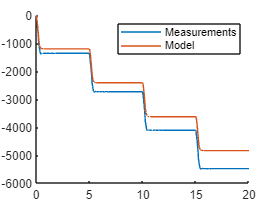

close all
figure
hold on

plot(0:Ts:20, Y_base)       %Plotting measurements
plot(-1*out.Y_sim_1)        %Plotting model estimation
legend('Measurements' , 'Model')


norm(Y_base - out.Y_sim_1.Data)/length(Y_base)      %RMS error of model

ans = 69.8899

### Second Approach

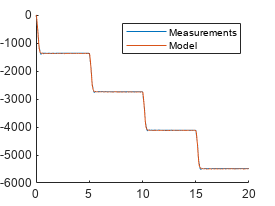

figure
hold on
plot(0:Ts:20, Y_base)
plot(out.Y_sim_2)
legend('Measurements' , 'Model')


norm(Y_base-out.Y_sim_2.Data)/length(Y_base)

ans = 0.1300

## Out of sample validation

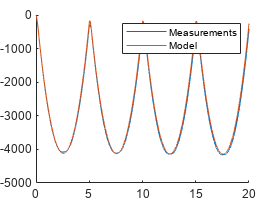

Base_valid = load("./Datas_acquisition/Validation_base_model.mat");
data_val = Base_valid.data_03_Mar_2023_12_21_30;
Y_model = lsim(Base_model_2, data_val(3, :), 0:Ts:20);
Y_real = data_val(2, :)';

figure
hold on
plot(0:Ts:20, Y_real)
plot(0:Ts:20, Y_model)
legend('Measurements' , 'Model')


norm(Y_real-Y_model)/length(Y_real)

ans = 0.8830

## Tuning

%Base_controller = pidTuner(Base_model_2, "PI");